# Solution to *UAV Capabilities III* exercise

The file `UAVData.xls` contains four columns of data on 33 unmanned aerial vehicles (UAVs). The first column contains the names of the UAVs; the next three columns contain numeric data: endurance (hours), payload (pounds), and operational altitude ceiling (feet), respectively.

## 1. Import data

UAV = readtable('UAVData.xlsx');

## 2. Sort by ceiling

byCeiling = sortrows(UAV,'AltitudeCapability','descend');

## 3. Plot ceiling as function of payload

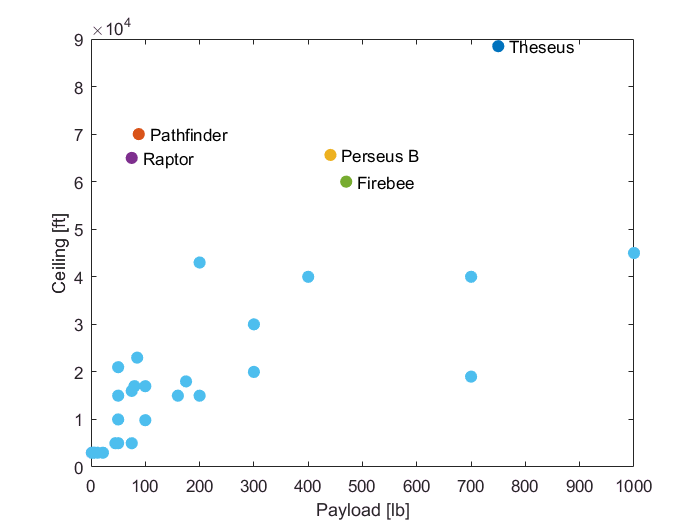


for k = 1:5
    plot(byCeiling.PayloadWeight(k),byCeiling.AltitudeCapability(k),...
        '.','MarkerSize',25)
    hold on
    text(byCeiling.PayloadWeight(k)+20,byCeiling.AltitudeCapability(k),...
        byCeiling.UnmannedAerialVehicle{k})
end
plot(byCeiling.PayloadWeight(k+1:end),byCeiling.AltitudeCapability(k+1:end),...
        '.','MarkerSize',25)
hold off
xlabel('Payload [lb]')
ylabel('Ceiling [ft]')